[MotionData]=ParseMatlabApp('nathanonemin.mat')

MotionData = struct with fields:
            Accel: [3098×3 double]
      Orientation: [3098×3 double]
           AngVel: [3098×3 double]
          t_Accel: [3098×1 double]
    t_Orientation: [3098×1 double]
         t_AngVel: [3098×1 double]
       accel_rate: 52.6316
      orient_rate: 52.6316
      AngVel_rate: 52.6316


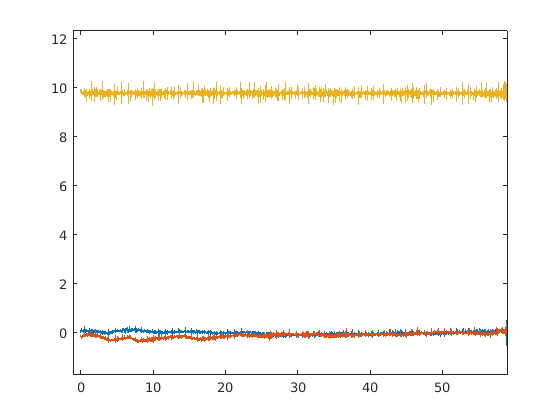

plot(MotionData.t_Accel, MotionData.Accel)

Fs = MotionData.accel_rate

Fs = 52.6316

N = length(MotionData.t_Accel)

N = 3098

z_fft = fft(MotionData.Accel(:, 3))

z_fft = 	1.0e+04 *

   3.0310 + 0.0000i
  -0.0002 - 0.0008i
   0.0000 + 0.0000i
   0.0002 - 0.0004i
   0.0001 - 0.0000i
  -0.0002 - 0.0003i
  -0.0000 - 0.0002i
  -0.0001 + 0.0001i
  -0.0001 - 0.0002i
  -0.0001 - 0.0001i


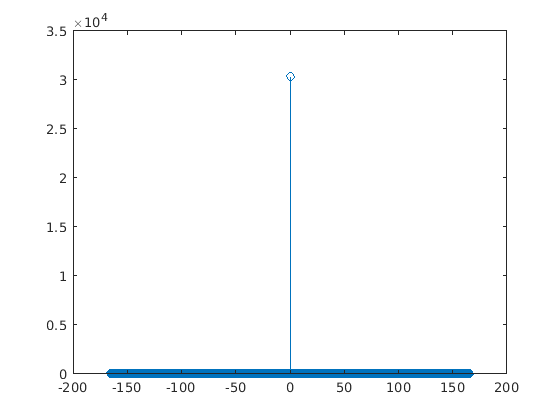

z_fft_shift = fftshift(z_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(z_fft_shift))


maxk(abs(z_fft), 5)

ans = 	1.0e+04 *

    3.0310
    0.0021
    0.0021
    0.0021
    0.0021


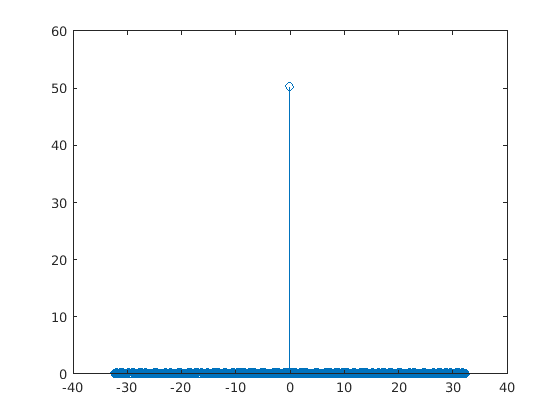

x_fft = fft(MotionData.Accel(:, 1));
x_fft_shift = fftshift(x_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(x_fft_shift))

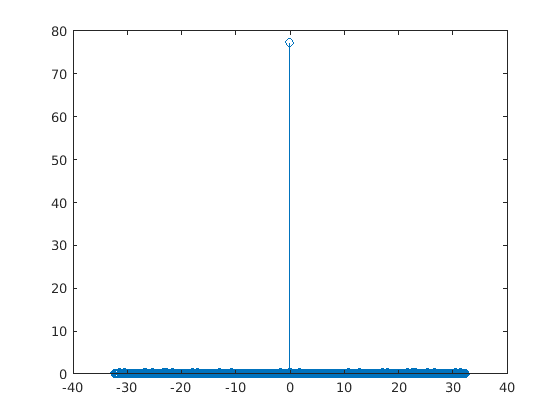

y_fft = fft(MotionData.Accel(:, 2));
y_fft_shift = fftshift(y_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(y_fft_shift))